# Atividade 04_05

Otávio Baziewicz Filho - 1942808

## Clear Workspace

clear all;
close all;
clc;

## Equalização do histograma na unha

Fazer a equalização do histograma de uma imagem na unha. Pode usar a função cumsum. Mostrar a imagem gDSC04422m16.png processada com o seu programa e com o histeq(I,256)do MATLAB e o histograma de cada uma. Os passos para a equalização do histograma estão descritos abaixo.

1. Obter o histograma da imagem original.

2. Normalizar este histograma [dividir por M*N (número de pixels da imagem)].

3. Obter a cumulative distribution function (cdf) [acumular o histograma do passo 2, isto é, p(i) = (j=0 até i) de p(j)].

4. Transformar a cdf em níveis de cinza arredondados [multiplicar por 255 e transformar em uint8].

5. Aplicar o vetor do passo 4 como uma função de transformação sobre a imagem original, usando a função intlut do MATLAB.

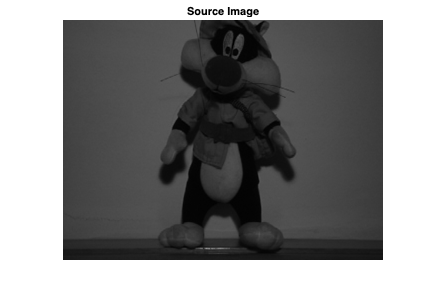

sourceImage = imread("gDSC04422m16.png");
builtinEqImage = histeq(sourceImage, 256);


figure, imshow(sourceImage)
title("Source Image")

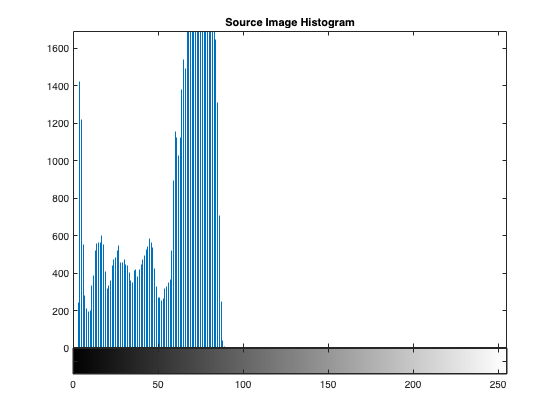


figure, imhist(sourceImage)
title("Source Image Histogram")

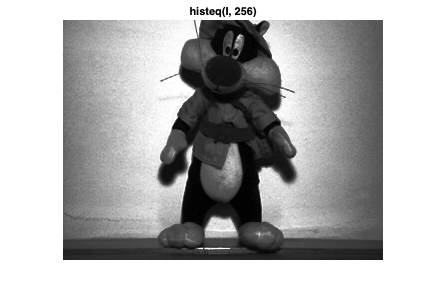


figure, imshow(builtinEqImage)
title("histeq(I, 256)")

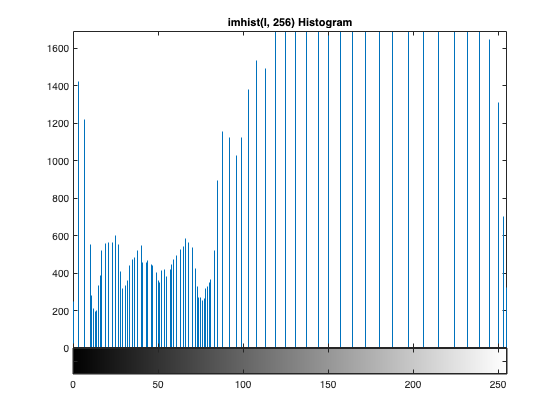


figure, imhist(builtinEqImage)
title("imhist(I, 256) Histogram")

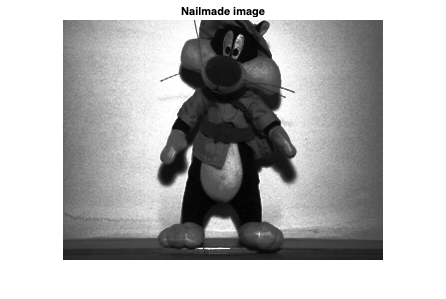


% Nailmade Eq

% 1
histogram = imhist(sourceImage);

% 2
[iMax, jMax] = size(sourceImage);
normalizationFactor = iMax * jMax;
normalizedHistogram = histogram ./ normalizationFactor;

% 3
cdf = cumsum(normalizedHistogram);

% 4
roundedGrayscaleCdf = uint8(cdf.*255);

% 5
nailmadeImage = intlut(sourceImage, roundedGrayscaleCdf);


figure, imshow(nailmadeImage)
title("Nailmade image")

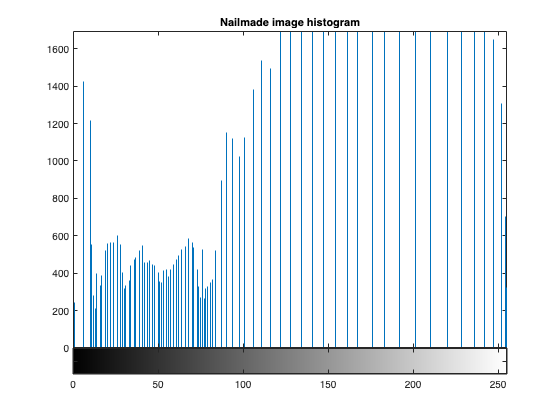


figure, imhist(nailmadeImage)
title("Nailmade image histogram")